# Eksamensæt

**M4STI1-01 Statistik for ingeniører -- 02-06-2023**

**Eksamensnummer -- 185432**

clear all
clf
format shortg

## 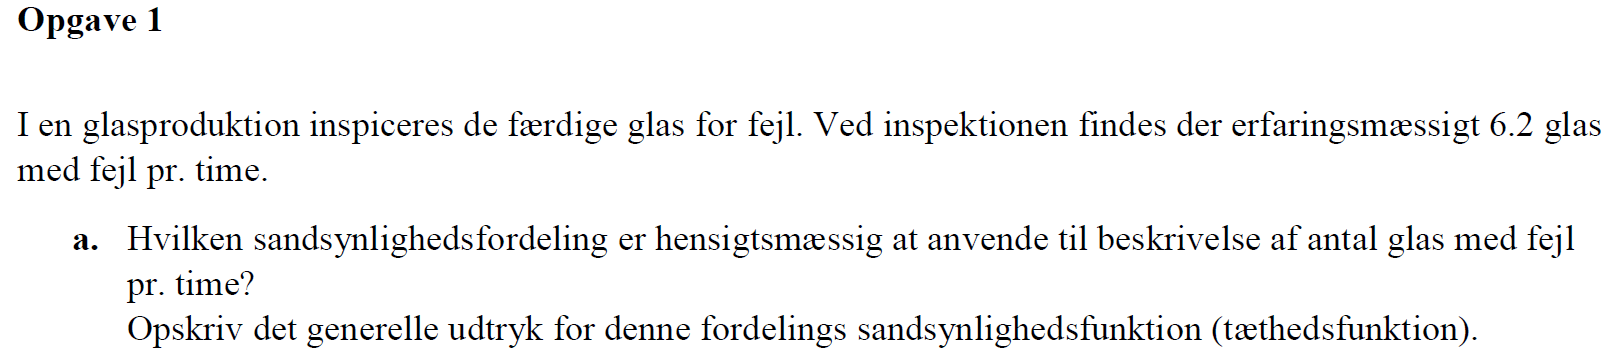

## a.

Da der tælles antal fejl på en time benyttes en poisson fordelling.

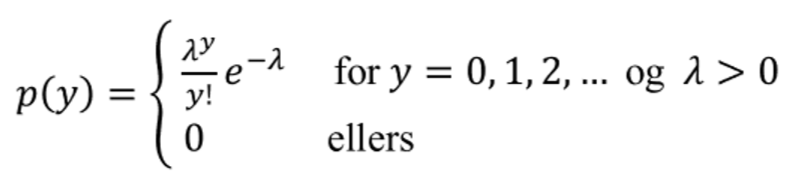

Dette er en god fordeling da man enten har en fejl eller ikke en fejl og sandsynligheden for at få noget der imellem er således = 0.

## b. Bestem fordelingens middelværdi, varians og standardafvigelse.

lambda = 6.2 % antal fejl pr. time

lambda =           6.2


mu = lambda % middel værdien

mu =           6.2


var = lambda % variansen

var =           6.2


std = sqrt(lambda) % standard afvigelsen

std =          2.49



$$\mu = 6,2$$



$$\sigma^2 = 6,2$$



$$\sigma = 2,49$$


### c. Bestem sandsynligheden for netop 4 glas med fejl.

Der benyttes den indbyggede propperbility density function i matlab.

Denne benytter formlen i opgave a gevet en y værdi og en gennesnitsværdi

Senere gøres dette også med cdf som er den kummulerede tæthedsfunction (sandsynlighed fra typisk 0 til x)

P_4 = poisspdf(4,mu)

P_4 =       0.12495


Således 12,5% sandsynlighed.

### d. Bestem sandsynligheden for mindst 5 glas med fejl.

P_5_or_more = 1 - poisscdf(4,mu)

P_5_or_more =       0.74082


Således 74,1% sandsynlighed.

### e. Bestem sandsynligheden for mindst 5 og højst 9 glas med fejl.

P_5_til_og_med_9 = poisscdf(9,mu) - poisscdf(4,mu)

P_5_til_og_med_9 =       0.64244


Således 64,2% sandsynlighed.

### f. Bestem sandsynligheden for netop 10 glas med fejl i et tilfældigt valgt interval på 2 timer.

Der formodes at der er et gennemsnit på $2 \cdot \mu$ på de to timer og dermed får vi:

poisspdf(10,2*mu)

ans =      0.097544


Således 9,8% sandsynlighed.

## Opgave 2

clear all
clf
format shortg

### a.

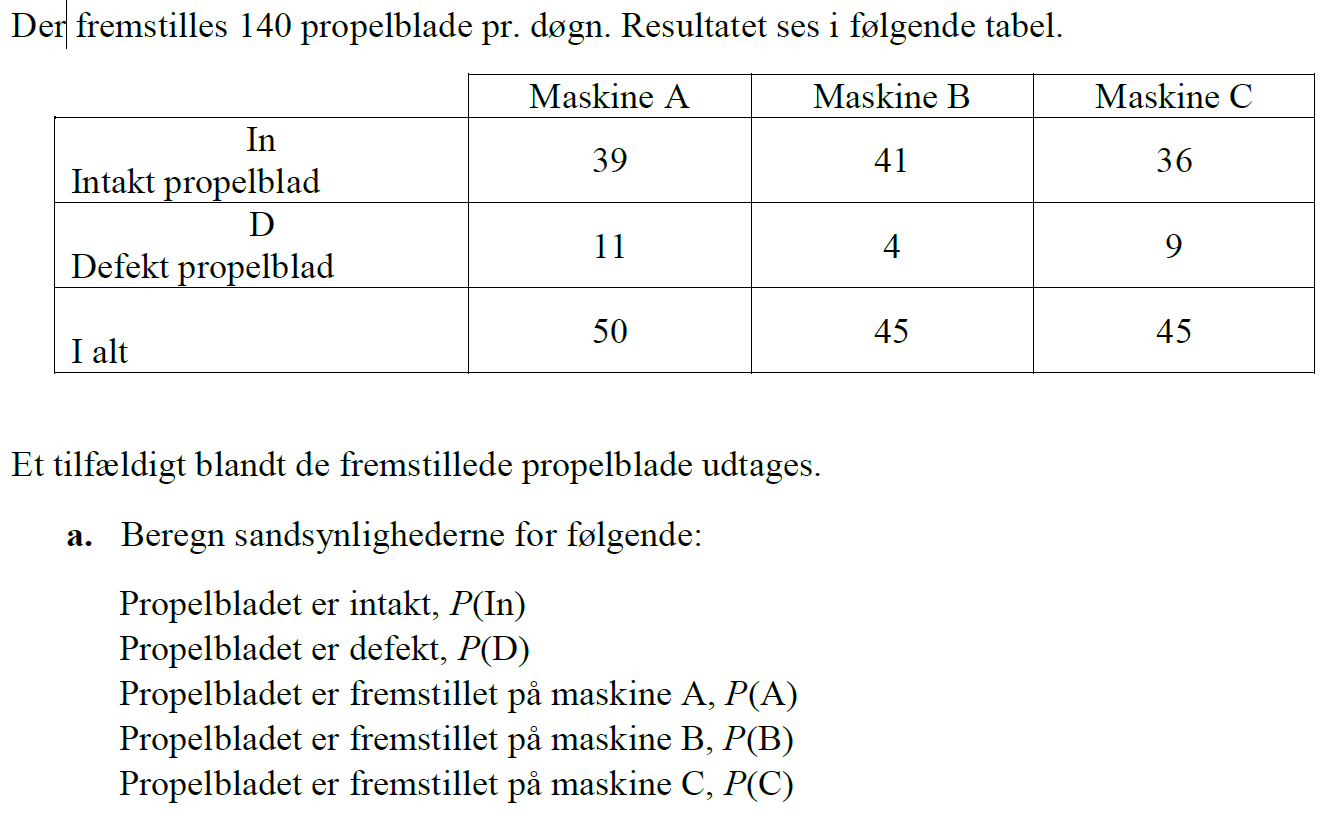

Vi opstiller først vores data

A_in = 39;
B_in = 41;
C_in = 36;

A_D = 11;
B_D = 4;
C_D = 9;

A_tot = 50;
B_tot = 45;
C_tot = 45;

tot = 140;
tot_in = A_in + B_in + C_in

tot_in =    116


tot_D = A_D + B_D + C_D

tot_D =     24


Vi finder nu sandsynlighederne

P_in = tot_in / tot

P_in =       0.82857


For intakt 82,9% sandsynlighed.

P_D = tot_D / tot

P_D =       0.17143


For defekt 17,1% sandsynlighed.

P_A = A_tot / tot

P_A =       0.35714


Producerede på maskine A 35,7% sandsynlighed.

P_B = B_tot / tot

P_B =       0.32143


Producerede på maskine B 32,1% sandsynlighed.

P_C = C_tot / tot

P_C =       0.32143


Producerede på maskine C 32,1% sandsynlighed.

### b. 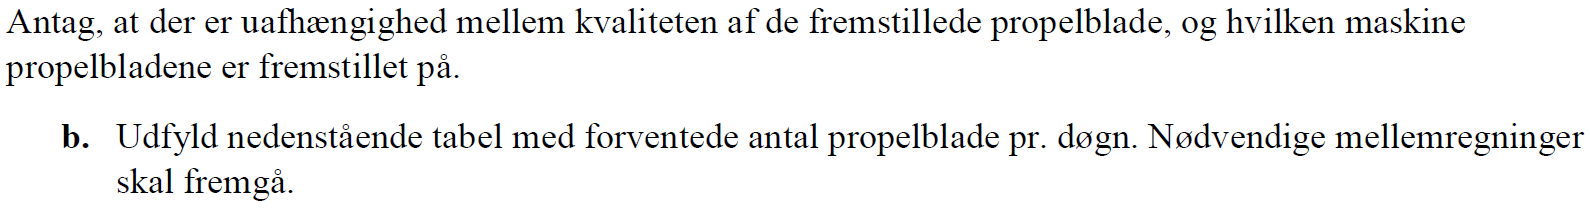

Vi finder forventede antal propelblade pr. døgn ved hver maskine intakte og defekte, ved at bruge den totale mængde, samt ved antagelse af uafhængighed kan vi gange sandsynligheden for hhv intakte og defekte blade sammen med sandsynligheden for at proppellen er producerede på den respektive maskine A, B eller C.

Her beskriver E at det er et antal af den totale mængde. procensatsen er en fælles hændelse. Hændelsen for fx in(intakte) og producerede på maskine A $P(In\cap A)$.

E_in_A = tot * P_in * P_A

E_in_A =        41.429


Intakte fra maskine A = 41 stk

E_in_B = tot * P_in * P_B

E_in_B =        37.286


Intakte fra maskine B = 37 stk

E_in_C = tot * P_in * P_B

E_in_C =        37.286


Intakte fra maskine C = 37 stk

E_D_A = tot * P_D * P_A

E_D_A =        8.5714


Defekte fra maskine A = 9 stk

E_D_B = tot * P_D * P_B

E_D_B =        7.7143


Defekte fra maskine B = 8 stk

E_D_C = tot * P_D * P_B

E_D_C =        7.7143


Defekte fra maskine C = 8 stk

Kol_names = {'Maskine A', 'Maskine B', 'Maskine C', 'I alt'};
row_names = {'In', 'D', 'I alt'};
table(round([E_in_A; E_D_A; E_in_A+ E_D_A],0), ...
    round([E_in_B; E_D_B; E_in_B + E_D_B],0), ...
    round([E_in_C; E_D_C; E_in_C + E_D_C],0), ...
    round([tot_in; tot_D; tot],0), VariableNames=Kol_names, RowNames=row_names)

ans = 3×4 table
             Maskine A    Maskine B    Maskine C    I alt
             _________    _________    _________    _____

    In          41           37           37         116 
    D            9            8            8          24 
    I alt       50           45           45         140 


Således for vi den forventede tabel vist herover. Det bemærkes at intakte og defekte blades total ikke går helt op på grund af afrundinger.

I alle udregninger bruges dog de præcise komma tal.

### c.

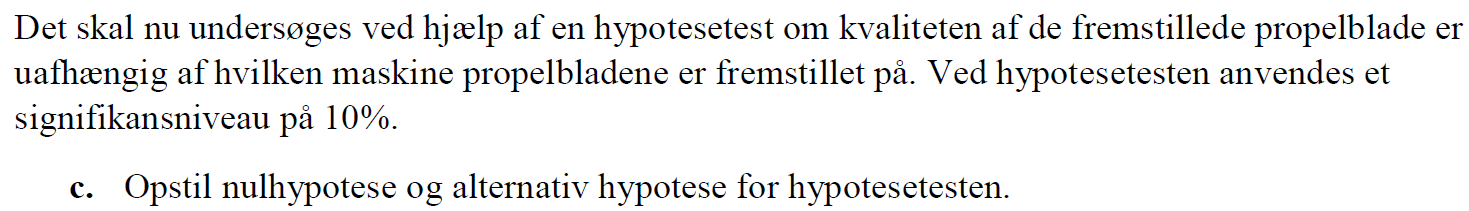

$H_0:$ kvaliteten af proppelerne er **uafhængig** af om de er producerede på maskine A, B og C

$H_a:$ kvaliteten af proppelerne er **afhængig** af om de er producerede på maskine A, B og C

### d. Opstil en formel for teststørrelsen (teststatistikken), og angiv hvilken fordeling den følger.

Vi tester for uafhængighed og benytter derfor in $\chi^2$ test hvor der summes over kollonner og rækker

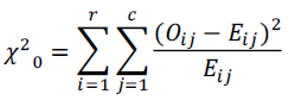

den følger en $\chi^2$ fordeling.

**e. Bestem den kritiske værdi og angiv det kritiske område for testen, når der vælges et signifikansniveau på 10%.**

alpha = 1 - 0.10 % signifikansniveau på 10%

alpha =           0.9


df = (2 - 1) * (3 - 1) % en to gange tre matrix estameres 

df =      2


chi_c = chi2inv(alpha, df) % den kritiske værdi

chi_c =        4.6052


Vi har nu at $\chi^2_0 < \chi^2_c = 4,6052$ for at forblive uden for det kritiske område og beholde $H_0$ hypotesen.

**f. Beregn teststørrelses (teststatistikkens) værdi. Mellemregninger skal fremgå.**

Vi finder de forskellige led i sumningen. i alt er der 6 led pga de 2 rækker og 3 kolonner. 

chi2_in_A = (A_in - E_in_A)^2 / E_in_A

chi2_in_A =       0.14236


chi2_D_A = (A_D - E_D_A)^2 / E_D_A

chi2_D_A =        0.6881


chi2_in_B = (B_in - E_in_B)^2 / E_in_B

chi2_in_B =       0.37001


chi2_D_B = (B_D - E_D_B)^2 / E_D_B

chi2_D_B =        1.7884


chi2_in_C = (C_in - E_in_C)^2 / E_in_C

chi2_in_C =      0.044335


chi2_D_C = (C_D - E_D_C)^2 / E_D_C

chi2_D_C =       0.21429


Vi kan nu summer ledene sammen til at finde vores $\chi^2_0$. (ligningen fra opgave d benyttes)

chi2_0 = chi2_in_A + chi2_D_A + chi2_in_B + chi2_D_B + chi2_in_C + chi2_D_C

chi2_0 =        3.2474


**g. Konkluder på hypotesetesten.**

Det ses at $\chi^2_0 = 3,2474 < 4,6052 = \chi^2_c$ og vi er kan således ikke forkaste vores $H_0$ hypotese.

Vi konkludere således at kvaliteten af bladene er ens ligegyldigt om de er alavet på maskine A, B eller C, med 90% sikkerhed. 

**h. Bestem p-værdien.**

p = 1 - chi2cdf(chi2_0,df)

p =       0.19716


Vi får nu en p-værdi på 0,20.

## Opgave 3

clear all
clf
format shortg
%vi henter data fra excel filen
data = xlsread("Statestik\Eksamens sæt\EKSAMEN\Data_M4STI1_2023F.xlsx", 'H:I');

### 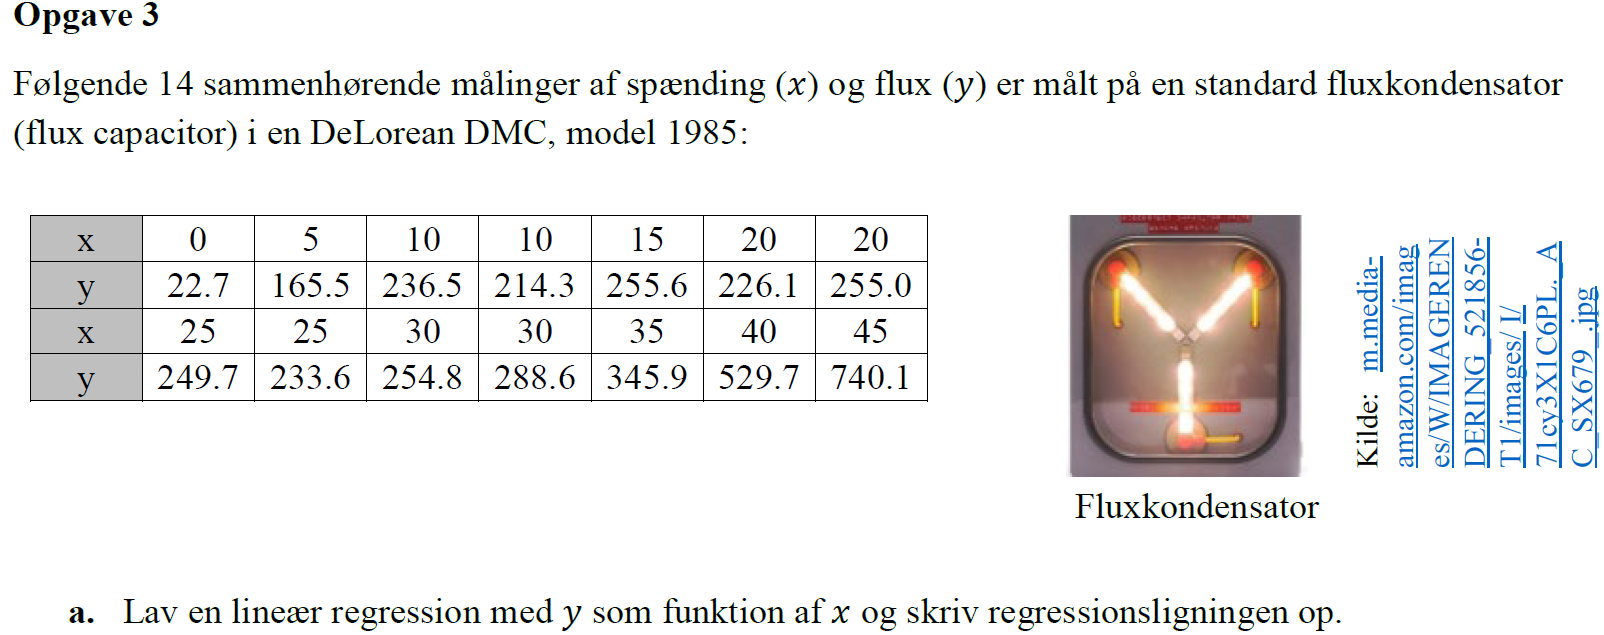

### a.

x = data(:,1);
y = data(:,2);
mdl = fitlm(x, y)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    ______    _______    __________

    (Intercept)      46.73     49.296    0.94795       0.36186
    x1              10.851     1.9283     5.6275    0.00011118


Number of observations: 14, Error degrees of freedom: 12
Root Mean Squared Error: 92.2
R-squared: 0.725,  Adjusted R-Squared: 0.702
F-statistic vs. constant model: 31.7, p-value = 0.000111

Vi får nu den lineær regressionsligningen


$$y(x) = 46,73 + 10,851 \cdot x$$


### b. Vurder ud fra regressionsanalysens statistikker (f.eks. R2, F og p-værdier), om modellen beskriver observationerne godt.

Modellen passer ikke særlig godt på dataene da vi har en lav $R^2_{adj}$ værdi på 0,702. Her vil vi gerne ha over 0,9. R-værdien er nemlig et mål for hvor stor en del af variationen i dataen der forklares af modellen.  Hvor $R^2_{adj}$ justere for antal parametre i modellen

p værdien fortæller også at skæringspunktet(intercept) ikke passer særlig godt med en p-værdi på 0,36 hvilket må formodes over et bestemt significant nivue.

F værdien og den lave p-værdi for $x_1$ fortæller dog at der kan være et sammenhæng mellem x og y.

### c. Lav et plot, der viser data og regressionsligningen. Diskutér sammenhængen mellem regressor- og responsvariablen.

Vi opstiller vores lineær funktion

y_fun = @(X) 46.73 + 10.851 * X

y_fun = function_handle with value:
    @(X)46.73+10.851*X


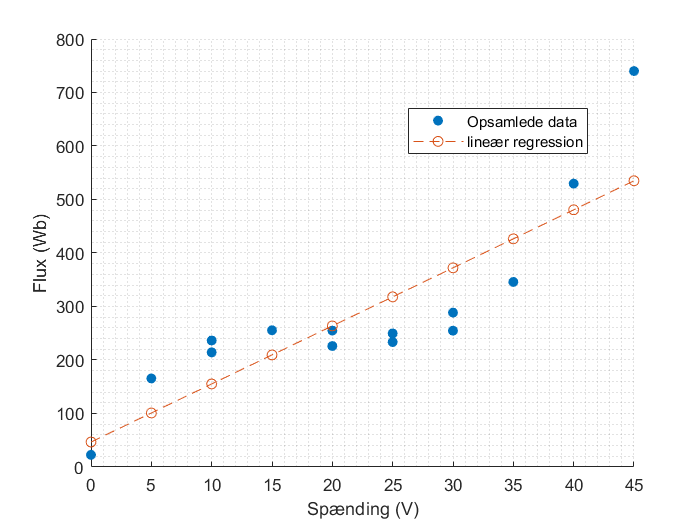

figure(1)
scatter(x, y, 'filled', DisplayName='Opsamlede data')
hold on
plot(x, y_fun(x), 'o--', DisplayName='lineær regression')
% lsline %alternativ kan der bruges lsline til at vise den lineær
% regrassion
xlabel('Spænding (V)')
ylabel('Flux (Wb)')
grid('minor')
legend('Location','best')
hold off

% man kunne også have plottet det som 
% plot(mdl) % fra fitlm tidliger for at få et hurtigt overblik 

I plottet ses dataen med en S form omkring regressionen. Dette siger mig at modellen ikke passer helt godt og især til sidst ser data ud til at "stikke lidt af" op af y-aksen. Dette kunne tyde på at en polynomium form.

### d.

### 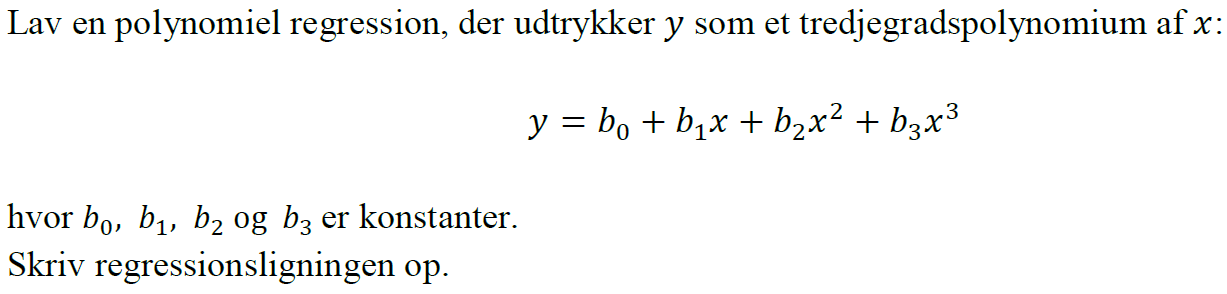

Vi benytter igen fitlm, dog modificerede

mdl2 = fitlm(x,y, 'y ~ x1 + x1^2 + x1^3')

mdl2 = Linear regression model:
    y ~ 1 + x1 + x1^2 + x1^3

Estimated Coefficients:
                   Estimate       SE         tStat       pValue  
                   ________    _________    _______    __________

    (Intercept)      27.325       14.127     1.9343      0.081848
    x1               35.085       2.6749     13.116    1.2604e-07
    x1^2            -1.8455      0.13924    -13.254     1.141e-07
    x1^3           0.031651    0.0020149     15.708    2.2424e-08


Number of observations: 14, Error degrees of freedom: 10
Root Mean Squared Error: 15.7
R-squared: 0.993,  Adjusted R-Squared: 0.991
F-statistic vs. constant model: 498, p-value = 3.5e-11

Således fås funktionen


$$y(x) = 27,325 + 35,085 \cdot x - 1,8455 \cdot x^2 + 0,031651\cdot x^3$$


**e. Er den polynomielle regressionsmodel bedre end den lineære model? Begrund dit svar.**

Ja modellen er meget bedre og tyder på at vores formodning om polynomium passede bedre.

Dette ses ud fra en $R^2_{adj}$ på 0,991 og de lave p-værdier. 

Kun p-værdien for skæringspunktet(intercept) på 0,082 kan være en lille smule ved siden af hvis vi ønsker et significans nivue på 5%.

**I det følgende skal du bruge modellen fra delopgave d. Hvis du ikke har besvaret delopgave d, kan du bruge modellen fra delopgave a.**

**f. Lav et residualplot, der viser studentiserede residualer mod **$\hat y$**. Diskutér resultatet.**

[yhat, yci] = predict(mdl2, x);

Vi finder de studentisrede residualer fra vores model lavet med fitlm

rst = mdl2.Residuals.Studentized; % Outlier punkter "unormale" værdier i y-retningen. abs(rst) skal gerne være mindre end 3

Vi kan nu opstille plottet.

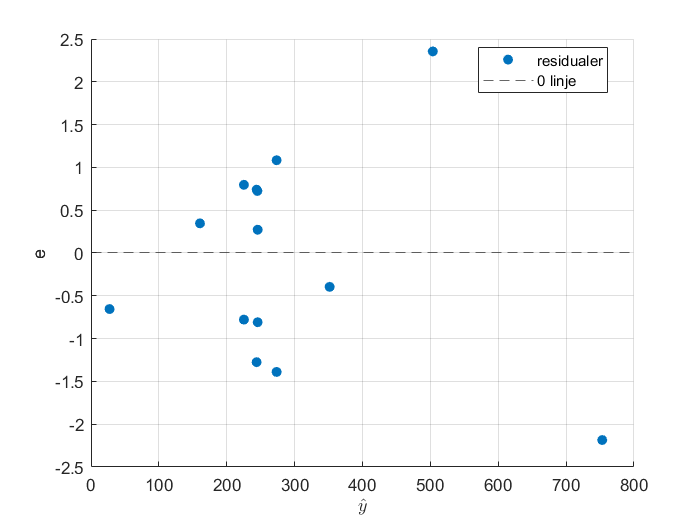

figure(2)
scatter(yhat, rst, 'filled', DisplayName='residualer')
yline(0, '--', DisplayName='0 linje')
xlabel('$\hat y$', Interpreter='latex')
ylabel('e')
grid('on')
legend('Location','best')

**g. Undersøg om der er unormale observationer i datasættet og angiv eventuelle unormale observationer med deres type (outliers, løftestangs-punkter eller indflydelsespunkter).**

Vi finder løftestang punkterne direkte fra fitlm således

lev = mdl2.Diagnostics.Leverage; %løfte punkter %'unormale' i x-retningen  % y hat 

Vi finder løfte punktets maximale værdi

c = 3; %antal regressor variable
n = length(rst); %antalt observationer
lev_limit = 2 * (c +1 )/ n

lev_limit =       0.57143


Vi kan nu sammenligne alle vores løftepunkter med max værdien

find(lev > lev_limit)

ans =      1
    14


Det findes at punkt 1 og 14 er løfte punkter (tabel vises nedenfor).

Vi kan nu se om vores residualer er størrer end 3 og dermed outliers.

find(abs(rst) > 3)


ans =

  0×1 empty double column vector



Ingen outliers findes.

Da vi skal ha at et punkt både skal være en outlier og et løfte punkt for at være etindflydelses punkt så kan det ses at der ikke er nogle indflydelses punkter.

nr = (1:length(rst))'; 
disp(table(nr, x, y, lev, rst, yhat))

    nr    x       y        lev        rst        yhat 
    __    __    _____    _______    ________    ______

     1     0     22.7    0.80909    -0.65452    27.325
     2     5    165.5    0.25114     0.34643    160.57
     3    10    236.5    0.22474     0.79663    225.28
     4    10    214.3    0.22474      -0.778    225.28
     5    15    255.6    0.20192     0.72448    245.18
     6    20    226.1    0.14794      -1.275    244.03
     7    20      255    0.14794     0.73926    244.03
     8    25    249.7    0.14448     0.27185    245.55
     9    25    233.6    0.14448    -0.80857    245.55
    10    30    254.8    0.19809     -1.3895    273.49
    11    30    288.6    0.19809      1.0836    273.49
    12    35    345.9     0.2337    -0.39542    351.58
    13    40    529.7    

h. Beregn den forventede værdi af y, når x=27. Beregn et interval for værdier af y, hvor 95 % af målinger med x=27 må forventes at ligge indenfor.

Vi laver antager en t fordeling pga. da spredningen af populationen er ukendt og at det forventes at den centrale grænseværdi sætning er overholdt. Således finder vi konfidensintervallet med

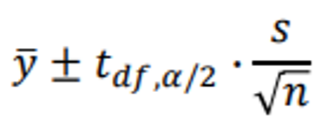

alpha = 0.05;
s = std(x) % standardafvigelsen for stikprøven

s =         13.26


n = length(x) % antal målinger (stikprøvens størrelse)

n =     14


df = n-1 % frihedsgrader

df =     13


B = tinv(1 - alpha/2, df) * s/sqrt(n) % vores +- værdi

B =         7.656


Vi opskriver formlen fundet i opgave **d** og finder vælrdien ved x=27

y_mod = @(x) 27.325 + 35.085 * x - 1.8455 * x^2 + 0.031651 * x^3;
y_27 = y_mod(27)

y_27 =        252.24


Vi kan nu finde min og max værdien.

[y_27 - B, y_27 + B]

ans =        244.58       259.89


Således for vi $y(27) = 252,24\pm 7,656$ Wb med 95% konfidens.

## Opgave 4

clear all
clf
format shortg

### a.

Kan beskrives med nr 2: $(A\cap C) \cap B^C$ og nr 5: $(A \cap  B^C) \cap (C \cap  B^C)$

### b.

Kan beskrives med nr 1: $A\cap C$ 

### c.

Kan beskrives med nr 4: $(A\cap C \cap B^C) \cup (B \cap C \cap A^C)$